## **AUTOMATED SIMULATION**

% Load parameters
clear all
clc;

load('parameters.mat');

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stair_gain = 1;   % takes values in {-1, 1}
simul.ramp_gain = 1;    % takes values in [0,1]
simul.stepdeg = 0;      % sets the step amplitude of the deg step
simul.antiWindUp = 1;   % takes values in {-1, 1} -1 anti-windup loop deactivated 1 activated

warning('off','all')

### **ANTI-WINDUP**

simul.select1 = 1;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.select2 = 1;      % takes values in {1, 2, 3} = {step, stair, ramp}
simul.stepdeg = 360;
simul.antiWindUp = 1;

awu.a = 0.1;              % this should be adjusted
awu.Tw = perf.ts5/awu.a;
awu.Kw = 1/awu.Tw;

anti_windup_step = sim('lab1_anti_windup','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_anti_windup/PID/FIX  (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)


save('anti_windup_step.mat','anti_windup_step');

% deactivatin anti windup and redoing the simulation

simul.antiWindUp = -1;

no_anti_windup_step = sim('lab1_anti_windup','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_anti_windup/PID/FIX  (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Quantizer (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/DAC/Saturation (discontinuity)
lab1_anti_windup/Quanser SRV-02 + NI DAQ/Quanser SRV-02 (discontinuity)


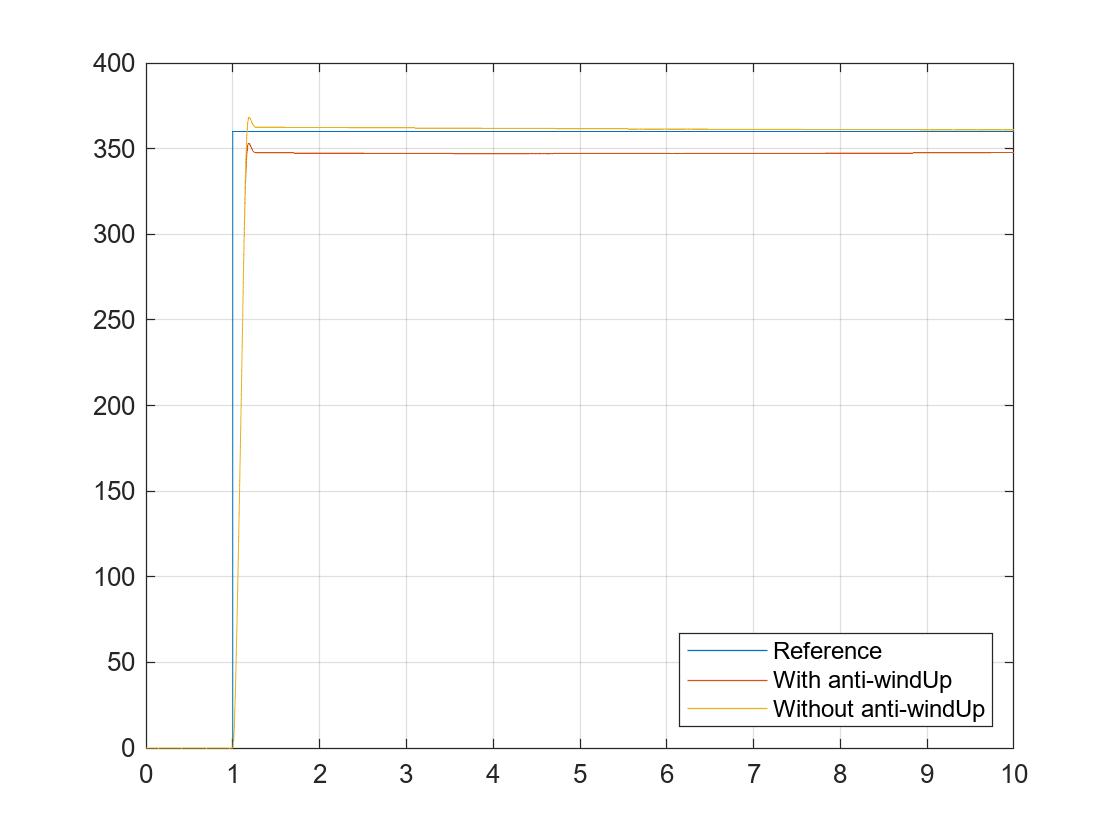

save('no_anti_windup_step.mat','no_anti_windup_step');

%plotting compared results
figure
title('Anti-WindUp: Step Reference')
plot(anti_windup_step.thref.time, anti_windup_step.thref.signals.values);
hold on;
plot(anti_windup_step.thl_meas.time, anti_windup_step.thl_meas.signals.values);
hold on;
plot(no_anti_windup_step.thl_meas.time, no_anti_windup_step.thl_meas.signals.values);
grid on;
legend('Reference','With anti-windUp', 'Without anti-windUp','Location','southeast');

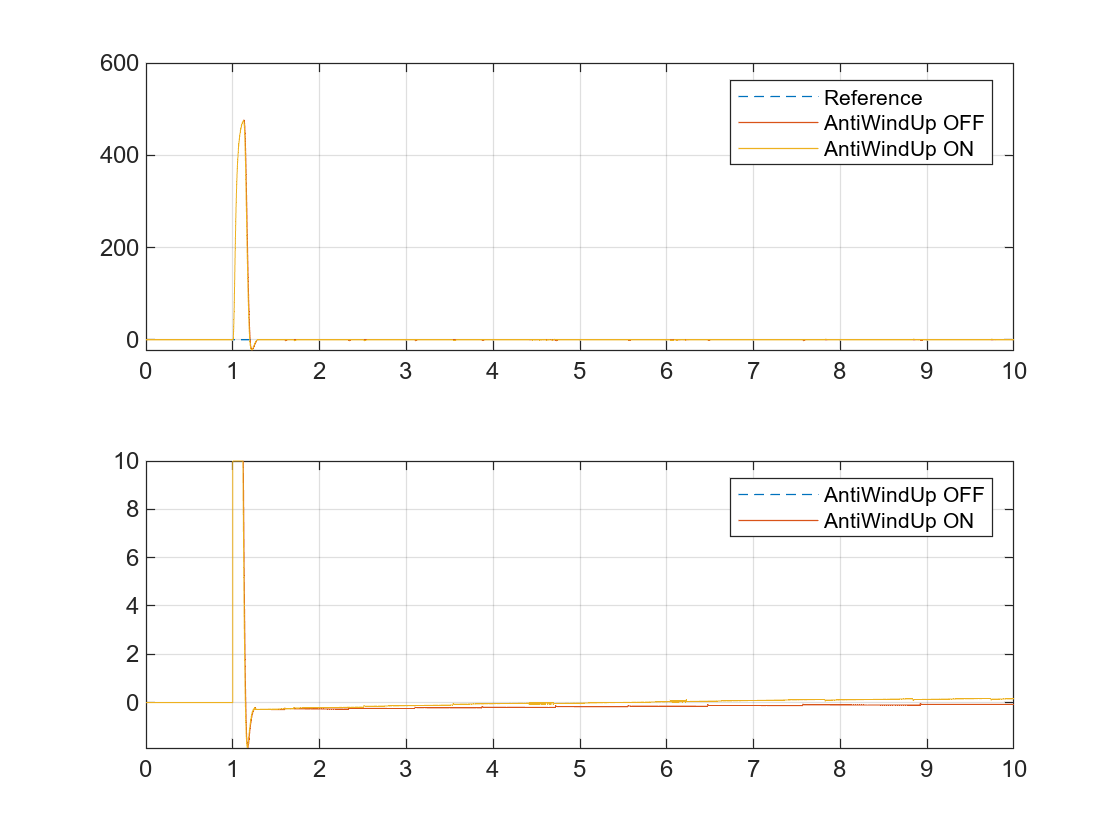


figure
title('Feedforward Results Comparison')
subplot(2,1,1);
plot(no_anti_windup_step.wref.time, no_anti_windup_step.wref.signals.values,'--');
hold on;
plot(no_anti_windup_step.wl_meas.time, no_anti_windup_step.wl_meas.signals.values);
plot(anti_windup_step.wl_meas.time, anti_windup_step.wl_meas.signals.values);
legend('Reference', 'AntiWindUp OFF','AntiWindUp ON')
grid on;
subplot(2,1,2);
plot(no_anti_windup_step.u.time, no_anti_windup_step.u.signals.values,'--');
hold on;
plot(no_anti_windup_step.u.time, no_anti_windup_step.u.signals.values);
plot(anti_windup_step.u.time, anti_windup_step.u.signals.values);
legend('AntiWindUp OFF','AntiWindUp ON')
grid on;

### FEED-FORWARD

simul.select1 = 3;      % takes values in {1, 2,3} = {deg, rpm, rpm/s} reference
simul.FFW = 1;          % enables FFW, set 0 to disable

feedforward_sim = sim('lab1_feedforward','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_feedforward/Feedforward compensator/Sum1
lab1_feedforward/Feedforward compensator/Sum2
lab1_feedforward/Feedforward compensator/Sum3
lab1_feedforward/Feedforward compensator/FIX  (discontinuity)
lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
<a href="matlab:open_and_hilite_hyperlink ('lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer','error')">lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer<

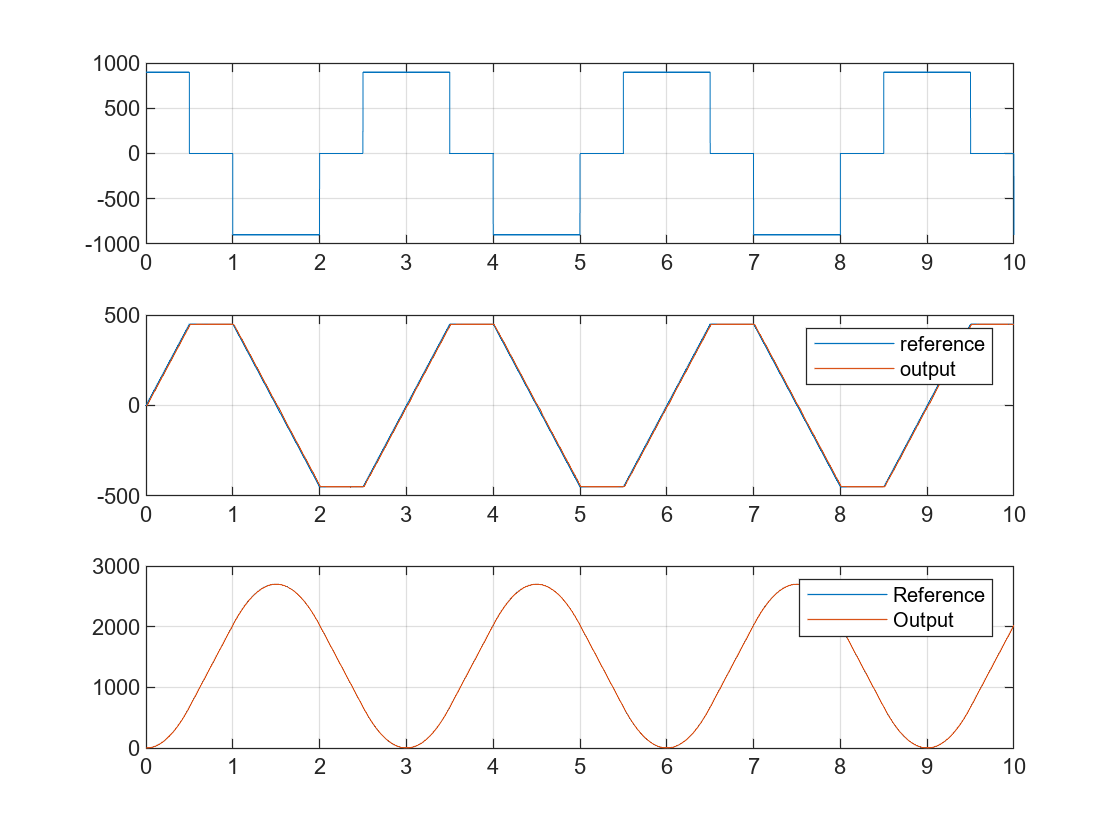

save('feedforward_sim.mat','feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(feedforward_sim.aref.time, feedforward_sim.aref.signals.values);
grid on;
subplot(3,1,2);
plot(feedforward_sim.wref.time, feedforward_sim.wref.signals.values);
hold on;
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(feedforward_sim.thref.time, feedforward_sim.thref.signals.values);
hold on;
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

simul.FFW = 0;          % enables FFW, set 0 to disable

no_feedforward_sim = sim('lab1_feedforward','StartTime','0','StopTime','10');

Found algebraic loop containing: 
lab1_feedforward/Feedforward compensator/Sum1
lab1_feedforward/Feedforward compensator/Sum2
lab1_feedforward/Feedforward compensator/Sum3
lab1_feedforward/Feedforward compensator/FIX  (discontinuity)
lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold
<a href="matlab:open_and_hilite_hyperlink ('lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer','error')">lab1_feedforward/Quanser SRV-02 + NI DAQ/DAC/Quantizer<

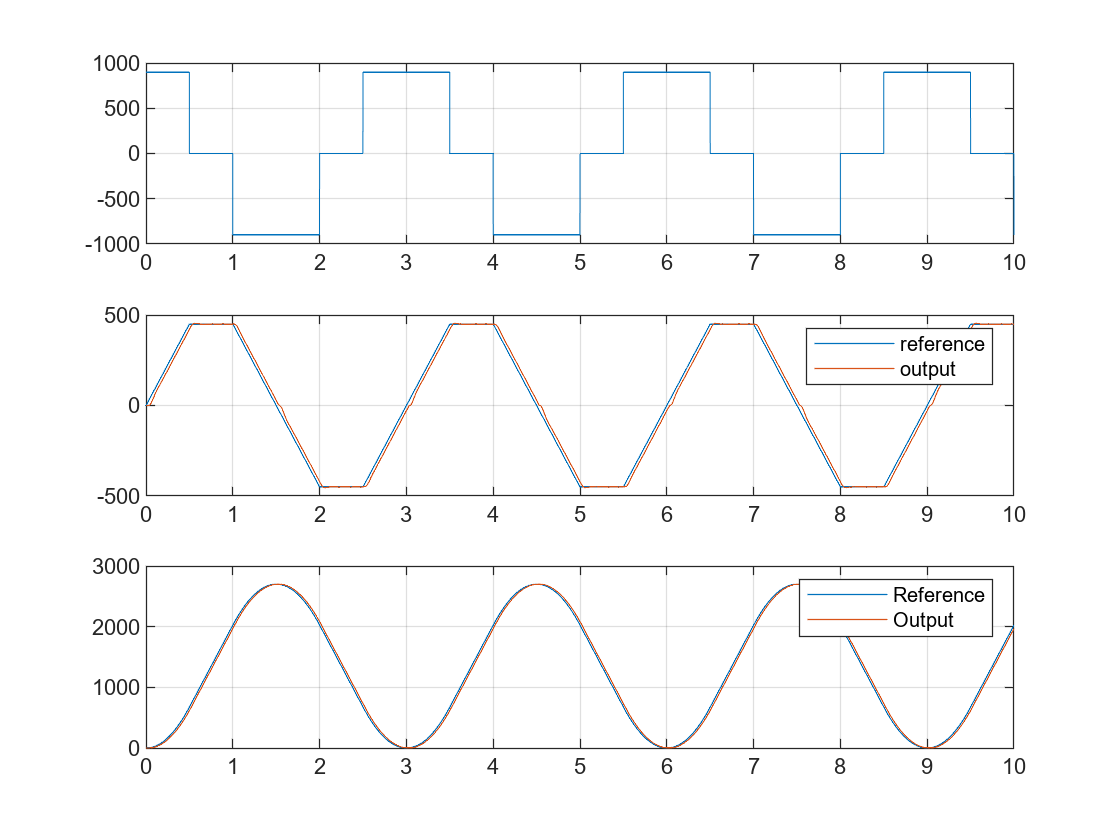

save('no_feedforward_sim.mat','no_feedforward_sim');

figure
title('Feedforward Results')
subplot(3,1,1);
plot(no_feedforward_sim.aref.time, no_feedforward_sim.aref.signals.values);
grid on;
subplot(3,1,2);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values);
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
legend('reference', 'output')
grid on;
subplot(3,1,3);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values);
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Output')
grid on;

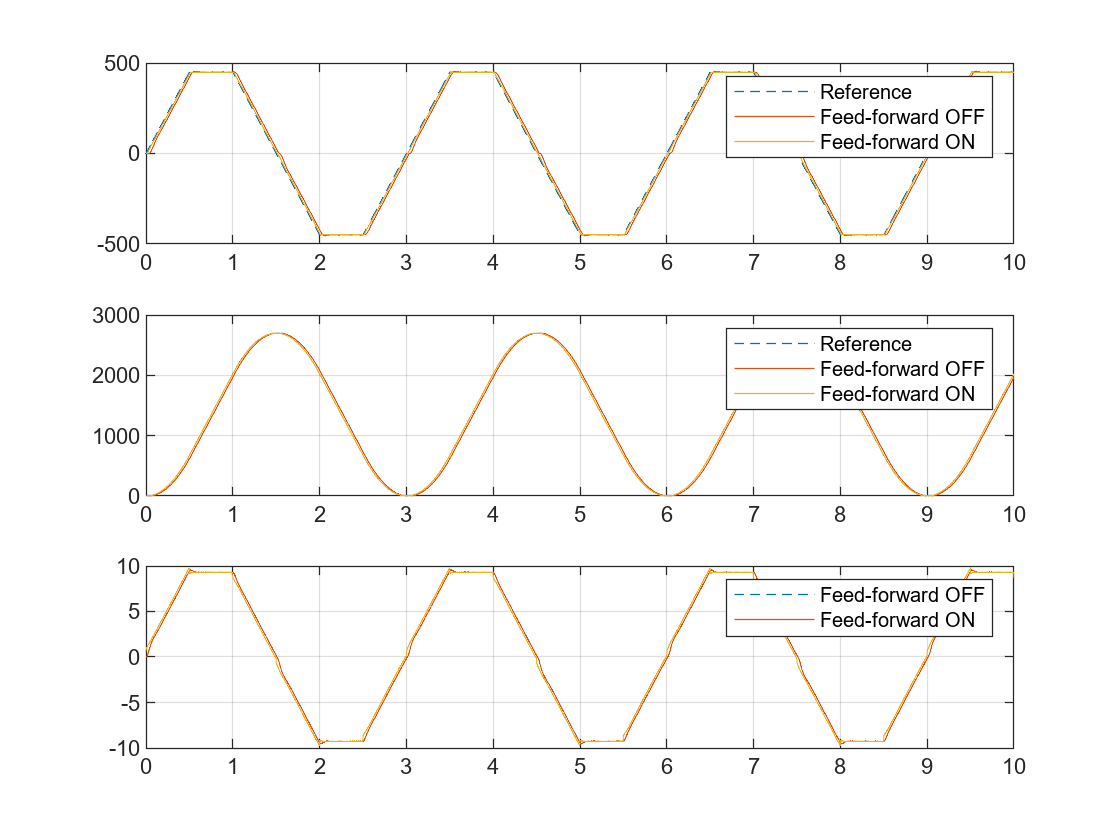

figure
title('Feedforward Results Comparison')
subplot(3,1,1);
plot(no_feedforward_sim.wref.time, no_feedforward_sim.wref.signals.values,'--');
hold on;
plot(no_feedforward_sim.wl_meas.time, no_feedforward_sim.wl_meas.signals.values);
plot(feedforward_sim.wl_meas.time, feedforward_sim.wl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
grid on;
subplot(3,1,2);
plot(no_feedforward_sim.thref.time, no_feedforward_sim.thref.signals.values,'--');
hold on;
plot(no_feedforward_sim.thl_meas.time, no_feedforward_sim.thl_meas.signals.values);
plot(feedforward_sim.thl_meas.time, feedforward_sim.thl_meas.signals.values);
legend('Reference', 'Feed-forward OFF','Feed-forward ON')
grid on;
subplot(3,1,3);
plot(no_feedforward_sim.u.time, no_feedforward_sim.u.signals.values,'--');
hold on;
plot(no_feedforward_sim.u.time, no_feedforward_sim.u.signals.values);
plot(feedforward_sim.u.time, feedforward_sim.u.signals.values);
legend('Feed-forward OFF','Feed-forward ON')
grid on;